clear, clc, close all

s = serialport(comPort, baudRate);
configureTerminator(s, "LF");  % Assuming the device terminates lines with CR/LF
s.Timeout = 5;            % Increase timeout if needed
flush(s);                 % Clear any old data

% Send the command to request PLL setup
writeline(s, "SETUP=");
clear s;

% Set up the serial port
comPort = 'COM6';         % Adjust as needed
baudRate = 115200;        % Must match your device
s = serialport(comPort, baudRate);
configureTerminator(s, "LF");  % Assuming the device terminates lines with CR/LF
s.Timeout = 30;            % Increase timeout if needed
flush(s);                 % Clear any old data

% Specify number of samples to read
numSamples = 100000;         % Adjust as needed

% Send the command to request raw data
cmd = sprintf("READRAW=%d", numSamples);
writeline(s, cmd);
pause(0.1);   % (Optional) a short pause to let the device start transmitting

% Preallocate a cell array to store raw messages.
% Each message is expected to contain exactly 8 characters (2 per channel).
rawMessages = cell(numSamples, 1);

% Collect the raw messages from the UART
for i = 1:numSamples
    try
        rawMessages{i} = read(s,10,"uint8");    % Read one line from the serial port
        %rawMessages{i} = strtrim(msg);  % Remove any whitespace/newline characters
    catch ME
        warning('Failed to read sample %d: %s', i, ME.message);
        break;
    end
end

% Close the serial port
clear s;

% Assume rawMessages is a cell array containing each 8-byte frame from UART
numSamples = numel(rawMessages);

sampleIndex = zeros(1, numSamples);
ch1 = zeros(1, numSamples);
ch2 = zeros(1, numSamples);
ch3 = zeros(1, numSamples);
ch4 = zeros(1, numSamples);

for i = 2:numSamples
    frame = rawMessages{i};
    if numel(frame) ~= 10
        warning('Frame %d is too short. Skipping.', i);
        continue;
    end
    
    % Convert each channel from little-endian: low byte comes first, then high byte.
    % SampleIndex: frame(1) = low_byte, frame(2) = high_byte
    sampleIndex(i) = uint16(uint8(frame(2))) * 256 + uint16(uint8(frame(1)));
    
    % Channel 1: frame(3) = low_byte, frame(4) = high_byte
    ch1(i) = uint16(uint8(frame(4))) * 256 + uint16(uint8(frame(3)));
    
    % Channel 2: frame(5) = low_byte, frame(6) = high_byte
    ch2(i) = uint16(uint8(frame(6))) * 256 + uint16(uint8(frame(5)));
    
    % Channel 3: frame(7) = low_byte, frame(8) = high_byte
    ch3(i) = uint16(uint8(frame(8))) * 256 + uint16(uint8(frame(7)));

    % Channel 4: frame(1) = low_byte, frame(2) = high_byte
    ch4(i) = uint16(uint8(frame(10))) * 256 + uint16(uint8(frame(9)));
end

% Display or process the channel data
ch1 = ch1*10/32768;
ch2 = ch2*10/32768;
ch3 = ch3*10/32768;
ch4 = ch4*10/32768;
disp('Data conversion complete');

Data conversion complete


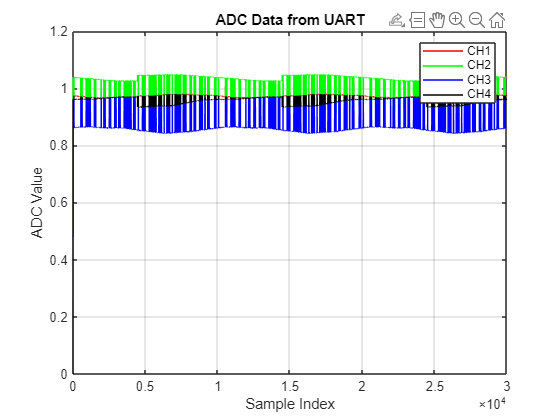

figure;
plot(sampleIndex, ch1, 'r', sampleIndex, ch2, 'g', sampleIndex, ch3, 'b', sampleIndex, ch4, 'k');
xlabel('Sample Index');
ylabel('ADC Value');
title('ADC Data from UART');
legend('CH1', 'CH2', 'CH3', 'CH4');
% ylim([3000,3500]);
grid on;

fch1 = fft(ch1);
fch2 = fft(ch2);
fch3 = fft(ch3);
fch4 = fft(ch4);
fsampling = 121000;
f = linspace(0,fsampling,length(fch1));

figure;
plot(f, fch1, 'r', f, fch2, 'g', f, fch3, 'b', f, fch4, 'k');

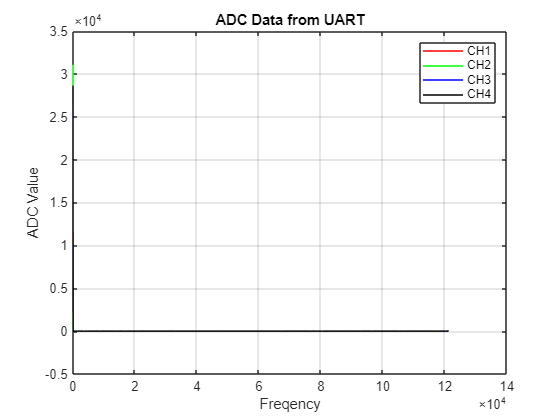

xlabel('Freqency');
ylabel('ADC Value');
title('ADC Data from UART');
legend('CH1', 'CH2', 'CH3', 'CH4');
% ylim([3000,3500]);
grid on;